# Chapter 01 — CPU Minimal Smoke Test

## Purpose

- This chapter confirms that the topic-mapping workflow

- can run end-to-end on a CPU-only MATLAB environment

- using a local JSONL/CSV input.

It produces a minimal diagnostic artifact (PNG + manifest).

clear; clc;

mlxPath = matlab.desktop.editor.getActiveFilename();
assert(strlength(mlxPath) > 0, "Cannot resolve active file path. Open this .mlx in the Editor and run it.");
examplesDir = fileparts(mlxPath);
repoRoot    = fileparts(examplesDir);
addpath(fullfile(repoRoot,"src"));  % avoid genpath pollution
rehash;

% Bootstrap: define this repo as the OpenAlex hub (session-local)
hubRoot = repoRoot;
setenv("OPENALEX_MATLAB_HUB", hubRoot);

cfg = topicmap.setup("HubRoot", hubRoot);
cfg = topicmap.env_check(cfg);

[topicmap.env_check] OK: required checks passed. (mode=standalone)
  Chapter 01 ready: 1
  Chapter 02 ready: 1
  Chapter 03 ready: 1
  Chapter 04 ready: 1
  Chapter 05 ready: 1
  runDir: D:\workspace\github\matlab-openalex-analyze\data_processed\openalex-topicmap\runs\20251226_152256
  (runDir created)
[topicmap.env_check] INFO (2):
  - Pipeline repo not found (expected D:\workspace\github\matlab-openalex-analyze\matlab-openalex-pipeline\src). End-to-end fetch is optional.
  - Normalize repo not found (expected D:\workspace\github\matlab-openalex-analyze\matlab-openalex-normalize\src). Normalize step is optional.
[topicmap.env_check] NEXT (2):
  * Optional: clone matlab-openalex-pipeline under hubRoot if you want to fetch your own JSONL.
  * Optional: clone matlab-openalex-normalize if you want CSV-based workflows.


% ---- run output folder ----
cfg.runDir = topicmap.make_run_dir(cfg, "Ch01");

% ---- config (chapter-local) ----
maxRecords = 1000;      % read limit for JSONL
k = 20;                % arbitrary chapter default; diagnostic placeholder
replicates = 5;
maxIter = 1000;

% Ch_01 uses a fixed CPU-minimal path (PCA + k-means). Do not auto-select UMAP/HDBSCAN here.

## Step 1.1 — Load works data (JSONL / CSV)

haveCsv   = isfield(cfg,"sample") && isfield(cfg.sample,"worksCsv")   && strlength(string(cfg.sample.worksCsv))>0   && isfile(cfg.sample.worksCsv);
haveJsonl = isfield(cfg,"sample") && isfield(cfg.sample,"worksJsonl") && strlength(string(cfg.sample.worksJsonl))>0 && isfile(cfg.sample.worksJsonl);

assert(haveCsv || haveJsonl, ...
    "No sample input found. Set cfg.sample.worksJsonl (recommended) or cfg.sample.worksCsv.");

if haveJsonl
    W = topicmap.read_pipeline_jsonl(cfg.sample.worksJsonl, "maxRecords", maxRecords);
    T = struct2table(W);
else
    T = readtable(cfg.sample.worksCsv);
end

% Expect at least an ID column; tolerate different names
idCol = "";
cands = ["work_id","id","openalex_id"];
for c = cands
    if any(strcmpi(T.Properties.VariableNames, c))
        idCol = c; break;
    end
end
assert(strlength(idCol)>0, "worksCsv must include one of these columns: %s", strjoin(cands,", "));


## Step 1.2 — Prepare feature matrix (embeddings or TF-IDF)

haveEmb = isfield(cfg,"sample") && isfield(cfg.sample,"embeddingMat") && ...
          strlength(string(cfg.sample.embeddingMat))>0 && isfile(cfg.sample.embeddingMat);

if haveEmb
    S = load(cfg.sample.embeddingMat);
    assert(isfield(S,"X"), "embeddingMat must contain variable X (n x d).");
    X = S.X;

    % Optional: alignment by IDs if provided
    if isfield(S,"work_id")
        [lia, locb] = ismember(string(T.(idCol)), string(S.work_id));
        if any(~lia)
            warning("Some works rows not found in embeddings; filtering to intersection.");
        end
        T = T(lia,:);
        X = X(locb(lia),:);
    end
else
    % Fallback: build a lightweight TF-IDF matrix from available text fields.
    txt = strings(height(T),1);
    if any(strcmpi(T.Properties.VariableNames,"title"))
        txt = txt + " " + string(T.title);
    end
    if any(strcmpi(T.Properties.VariableNames,"abstract"))
        txt = txt + " " + string(T.abstract);
    end
    if all(strlength(strtrim(txt))==0)
        error("Ch01:NoText", "No text fields found (title/abstract). Provide embedding Mat or include text fields.");
    end
    docs = tokenizedDocument(txt);
    bag  = bagOfWords(docs);
    bag  = removeInfrequentWords(bag, 2);
    X    = tfidf(bag);
end

## Step 1.3 — Dimensionality reduction (PCA)

% Default to PCA for demo_01; if you flip plan.reducer later, you can insert UMAP.
rng(cfg.seed);

% pca() does not accept sparse input (e.g., TF-IDF). Convert if needed.
if issparse(X)
    X = full(X);
end

% Reduce to 5D then 2D via PCA (stable + fast)
[~, score5] = pca(X, "NumComponents", 5);
Z5 = score5;

[~, score2] = pca(Z5, "NumComponents", 2);
Z2 = score2;

## Step 1.4 — Clustering (k-means)

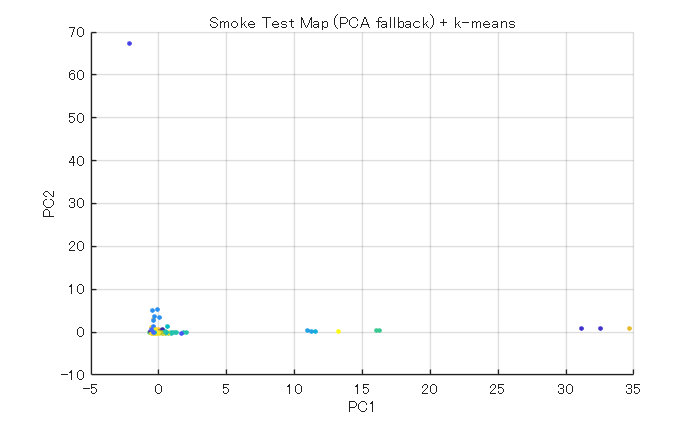

labels = kmeans(Z5, k, "Replicates", replicates, "MaxIter", maxIter);
%% Plot
fig = figure("Name","OpenAlex Smoke Test Map (PCA fallback)");
scatter(Z2(:,1), Z2(:,2), 8, labels, "filled");
title("Smoke Test Map (PCA fallback) + k-means");
xlabel("PC1"); ylabel("PC2");
grid on;

%% Save outputs into runDir
outPng = fullfile(cfg.runDir, "Ch_01_pca_kmeans.png");
set(fig, "Renderer", "painters");
drawnow;
exportgraphics(fig, outPng);
fprintf("Saved: %s\n", outPng);

## Step 1.5 — Save diagnostic outputs

manifest = struct();

Saved: D:\workspace\github\matlab-openalex-analyze\data_processed\openalex-topicmap\20251226_152258_Ch01\Ch_01_pca_kmeans.png


manifest.created_at = string(datetime("now"));
manifest.runDir = string(cfg.runDir);
manifest.k = k;
manifest.replicates = replicates;
manifest.seed = cfg.seed;
manifest.n = size(X,1);
manifest.d = size(X,2);
manifest.reducer = "pca(5)->pca(2)";
manifest.clusterer = "kmeans";
manifest.input_mode = ternary(haveEmb, "embeddingMat", "tfidf(title/abstract)");

outJson = fullfile(cfg.runDir, "Ch_01_manifest.json");
fid = fopen(outJson, "w");
fwrite(fid, jsonencode(manifest, PrettyPrint=true));
fclose(fid);

function y = ternary(cond, a, b)
    if cond, y = a; else, y = b; end
end

## Notes and scope limitations (Read before interpretation)

- This chapter demonstrates mechanics only.

- Outputs are diagnostic artifacts, not analytical results.

- Parameters such as k=20 are placeholders.

- No interpretability or scientific claims are made.